## Aim: Analyze the extracellular recording data

#### Step1: Do spike sorting, save the sorted files into another folder. The folder/files should be named with the following formate:

###              **   "O776\P01\O766_P01F1.pl2"**

O776: Birdname

P01: Position of your recording

F1: The 1st file of this recording

**When you save the sorted .pl2 files, select only SPKC, AI, SPKC_SPKC channel and unselect all the others**

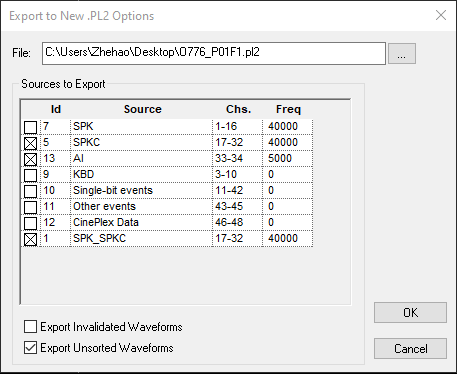

#### Step 2: Based on the raw data to generate .mat files that contained all the necessary information about sorted units. 

addpath(genpath("C:\Users\Zhehao\Dropbox (OIST)\My_Matlab\TEA"))
addpath(genpath("C:\Users\Zhehao\Dropbox (OIST)\My_Matlab\SAT_Modi"))
dbstop if error
[neuroster,malfunctions] = extractNeuronInfo("F:\ATest\O776");
error = Archon.batchGenAnalysis(neuroster,1);

%If error is not empty, run the following code to debug
[neuroster,malfunctions,cdrfroster] = Archon.extractAnalysisInfo("PATH_TO_THE_ERROR_FOLDER");
 Archon.genAnalysis_BasedOnRoster(neuroster);

#### Step 3: Load the data of the neuron you would like to check

loaded = load(PATH,'list');

#### Step4: If you would like to draw a spectrogram of your stimuli

figure;
Draw.spec(y,fs);

#### Step 5: If you would like to draw a raster plot

figure;
Draw.raster(sptimes,y,fs);


#### Step 6: If you would like to draw a spike density function

figure;
Draw.sdf(sptimes,y,fs);

#### Step 7: If you would like to align songspectrogram, raster plot and spike density function together

figure;
Draw.three(y,fs,sptimes);

#### **Step 8: To draw all the stimuli-response plot together:**

I = {};
for idx = 1: length(list)
    figure('Color','w','Position', [216 590 1274 447]);
    Draw.three(list(idx).plty,list(idx).fs,list(idx).pltsptimes);
    xlabel(sprintf('%s-%s',list(idx).stimuliname,list(idx).Fid));
    frame = getframe(gcf);
    I{idx} = frame.cdata;
    %                 saveas(gcf,sprintf('%s\\Stimulus_%s_%s.fig',outdir,sg.formated_name,list(idx).stimuliname));
    %                 saveas(gcf,sprintf('%s\\Stimulus_%s_%s.eps',outdir,sg.formated_name,list(idx).stimuliname),'epsc');
    %                 saveas(gcf,sprintf('%s\\Stimulus_%s_%s.svg',outdir,sg.formated_name,list(idx).stimuliname),'svg');
    close(gcf);
end
lieshu = 3;
hangshu = ceil(length(I)/lieshu);
rest = lieshu*hangshu - length(I);
white = uint8(255*ones(size(I{1})));

if rest > 0
    for k = 1:rest
        I = [I,white];
    end
end

reshapedI = reshape(I, lieshu,[])';
clear I
img = cell2mat(reshapedI);
imwrite(img,'Name_Of_The_Figure');


#### **Step9: If you would like to identify if a stimuli triggered significant response**

during_stimulus_number = cellfun(@length,list(1).sptimes); % if the pre- and during- duration is the same
pre_stimulus_spike_number = cellfun(@length,list(1).presptimes); % then we can directly use the spike number
[p,h] = signrank(during_stimulus_number,pre_stimulus_spike_number,'tail','left');

% Or if your data is normalized distribution:
[p,h] = ttest(during_stimulus_number,pre_stimulus_spike_number,'tail','left');


**Step10:If you would like to do Step8 for the whole stimuli-response list:**

for k = 1:length(list)

    during_stimulus_number = cellfun(@length,list(k).sptimes); % if the pre- and during- duration is the same
    pre_stimulus_spike_number = cellfun(@length,list(k).presptimes); % then we can directly use the spike number
    [p,h] = signrank(during_stimulus_number,pre_stimulus_spike_number,'tail','left');

    list(k).hvalue = h;
    list(k).pvalue = p;

end

**Step11: If you would like to check the waveform of your neurons;**

loaded = load(PATH,'waveform');

waveform.drawAll;

**Step11: To calculate the mean spike width**

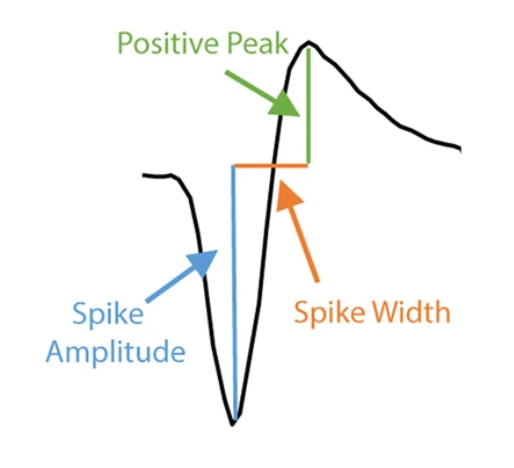

allwaveforms = waveform.all; % what you have loaded
%waveforms =  n.waveform;
[~,troughstime] = min(allwaveforms,[],2);
wavlen_units = [];

for k = 1: size(allwaveforms,1)
    this_wf = allwaveforms(k,:);
    [~,wavlen_units(k)] =  max(this_wf (troughstime(k):end));
end


meanWL =  mean(wavlen_units*(1/wv.adfreq)*1000); % ms